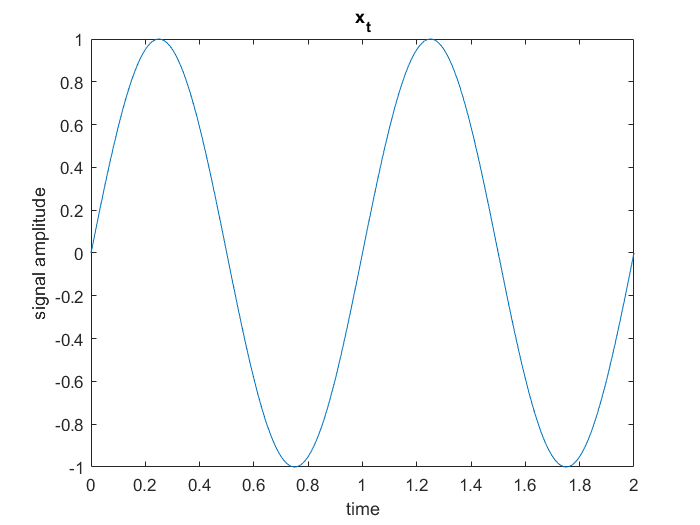


%Kourosh Moaveni Nejad
%9923124

%----------------------------------------------------------------------





%Defining time
t=[0:0.01:2];
%Frequency of signal(HZ)
f=1;


%Creation Desired Sinusoidal Signal
x_t=sin(2*pi*f*t);

%Creating the random signal with uniform distributed PDF in the range of
%[-0.5,0.5] and adding it to the x_t
random_signal=(rand(size(x_t))-0.05);
noisy_signal=random_signal+x_t;

%Plot and Stem
figure(1)
plot(t,x_t);
xlabel("time");
ylabel("signal amplitude")
title("x_t");

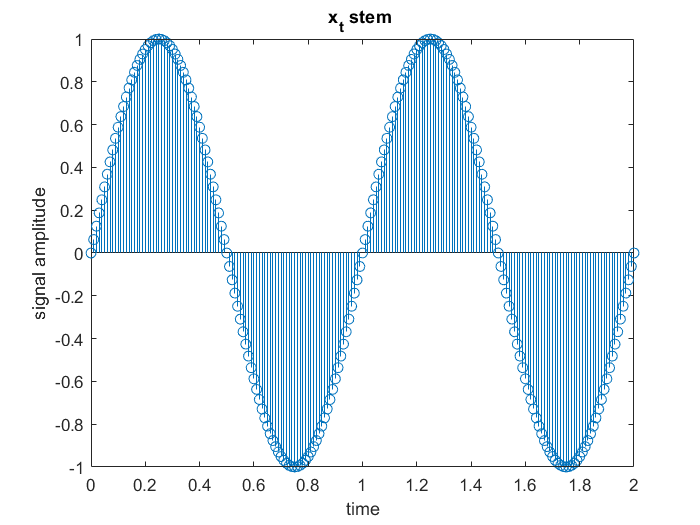


figure(2)
stem(t,x_t)
xlabel("time");
ylabel("signal amplitude")
title("x_t stem ");

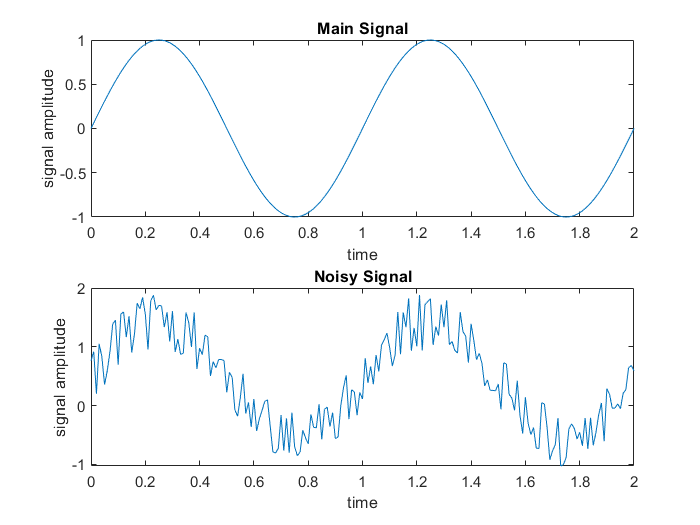


figure(3)
subplot(2,1,1);
plot(t,x_t);
xlabel("time");
ylabel("signal amplitude")
title("Main Signal");

subplot(2,1,2);
plot(t,noisy_signal);
xlabel("time");
ylabel("signal amplitude")
title("Noisy Signal");

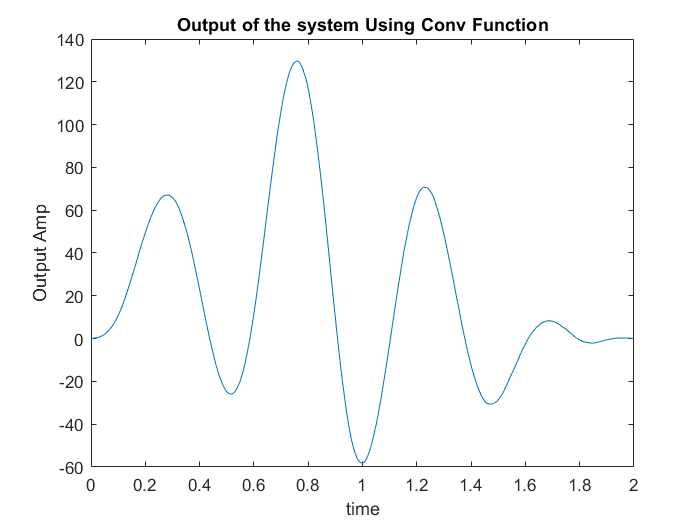


%-----------------------------------------------------------------

%SMA & Conv Func
h_t=sma(noisy_signal,20);
system_result=conv(noisy_signal,h_t);
t2=linspace(0,2,length(system_result));

figure(4)
plot(t2,system_result);
xlabel("time");
ylabel("Output Amp")
title("Output of the system Using Conv Function");

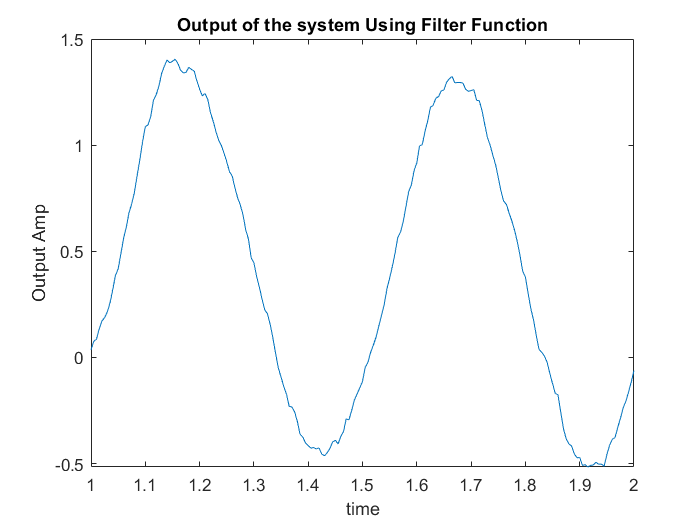


%-----------------------------------------------------------------

%Filter Func

system_result_2=filter(1/(1+21)*ones(1,21),1,noisy_signal);
t2=linspace(1,2,length(system_result_2));

figure(5)
plot(t2,system_result_2);
xlabel("time");
ylabel("Output Amp")
title("Output of the system Using Filter Function");


%------------------------------------------------------------------
 %Function singen(w,n)

singen(1000,100); %example



function res = singen(w,n)

% n = length , w= Frequency

U_n=ones(1,n);

k=[1:n];

res=sin(w*k).* U_n;



end











function moving_average= sma(data,m2)
 
 
 
 p={};
 for k=1:m2+1
     s=zeros(1,length(data)+m2);
     s(k:length(data)+k-1)=data;
     p{k}=s;
 end
 
 
 sum=0;
 for i=1:m2+1
     sum=sum+p{i};
 end    
     
 moving_average=(1/(m2+1))*sum;     
end      








